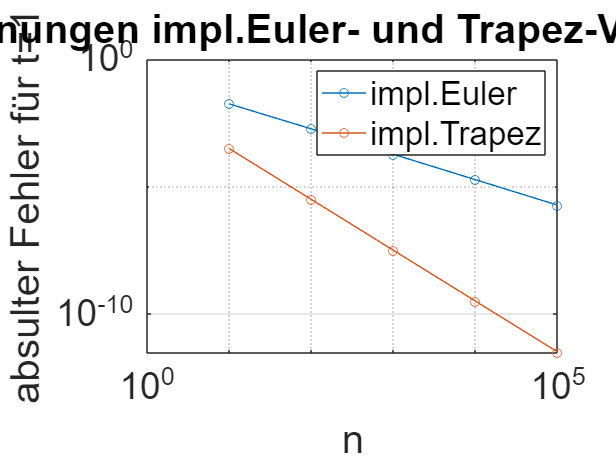

clear all
close all
func = @(t,y) -y;
dfunc = @(t,y) -1;
func_loes = @(x) exp(-x);

y_a = 1;
t_span = [0,1];
tol = 10^-6;
n = 10.^(1:5);
nmax = 100;


Abs_err_max_Euler = max_abs_fehler(@(n) impl_euler(func ,t_span ,y_a ,n ,dfunc, tol, nmax), func_loes, n);
Abs_err_max_Trapez = max_abs_fehler(@(n) impl_trapez(func ,t_span ,y_a ,n ,dfunc, tol, nmax), func_loes, n);

loglog(n,Abs_err_max_Euler,'o-','DisplayName','impl.Euler');
title('Ordnungen impl.Euler- und Trapez-Verfahren')
xlabel("n");
ylabel('absulter Fehler für t=1')
set(gca,'FontSize',25)
legend
grid on


hold on
loglog(n,Abs_err_max_Trapez,'o-','DisplayName','impl.Trapez')